# **Report 2**

## **Pouya Abginechi - 40023001**

## **Alisina Shahmohammadi - 40023041**

#### **6. Aliasing in Time:**

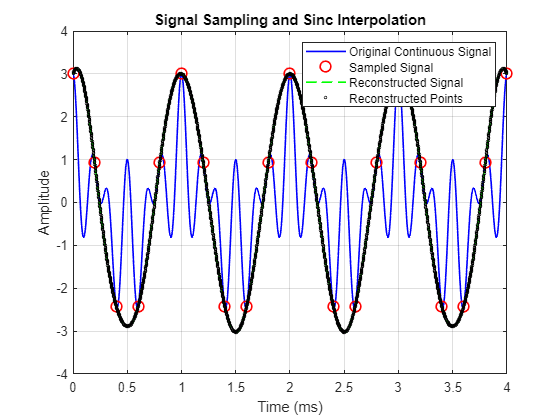

clc;
clear all;
close all;

% Frequencies of the components
f1 = 1000;    
f2 = 4000;    
f3 = 6000;    

% Sampling frequency (below Nyquist for testing)
Fs = 5000;   

% Time range
t_start = 0;  
t_end = 0.004;  

% High resolution time for continuous signal
dt = 1/(100 * f3); 
t_continuous = t_start:dt:t_end;

% Continuous-time signal (sum of 3 cosines)
x_continuous = cos(2*pi*f1*t_continuous) + ...
               cos(2*pi*f2*t_continuous) + ...
               cos(2*pi*f3*t_continuous);

% Sampled signal (discrete points)
t_sampled = t_start:1/Fs:t_end;
x_sampled = cos(2*pi*f1*t_sampled) + ...
            cos(2*pi*f2*t_sampled) + ...
            cos(2*pi*f3*t_sampled);

% Reconstruction via sinc interpolation (inline code)
t_reconstructed = t_continuous;
x_reconstructed = zeros(size(t_reconstructed));
for i = 1:length(t_reconstructed)
    sinc_values = sinc(Fs * (t_reconstructed(i) - t_sampled)); % sinc() is sin(pi*x)/(pi*x)
    x_reconstructed(i) = sum(x_sampled .* sinc_values);
end

% Plotting
figure;
plot(t_continuous*1000, x_continuous, 'b', 'LineWidth', 1.2); 
hold on;
plot(t_sampled*1000, x_sampled, 'ro','MarkerSize', 8, 'LineWidth', 1.2);
plot(t_reconstructed*1000, x_reconstructed, 'g--', 'LineWidth', 1.2);
plot(t_reconstructed*1000, x_reconstructed, 'ko', 'MarkerSize', 2);

xlabel('Time (ms)');
ylabel('Amplitude');
legend('Original Continuous Signal', 'Sampled Signal', 'Reconstructed Signal', 'Reconstructed Points');
title('Signal Sampling and Sinc Interpolation');
grid on;
hold off